Assignment 3:

Examining the probabilty density function (pdf) and cumulative density function (cdf) of the data set (60 measurements taken when target is absent (H0) and 50 taken when target is present (H1)). A threshold for presence determination is set as the intersection of the 2 curves: pdf given H1 and pdf given H0.

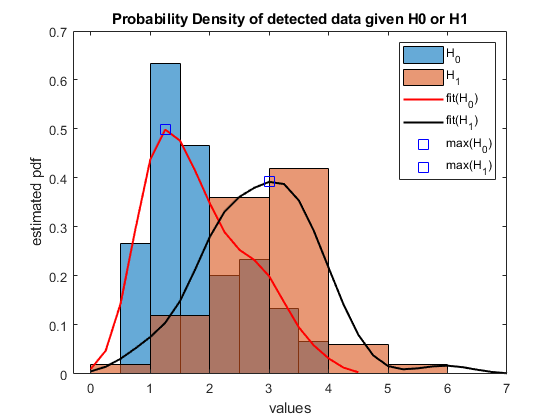

data = table2array(DoPhungHWPart2);
data = data(~isnan(data));
data_sorted_des = sort(data, 'descend');
target_abs = sort(data((1:60),:),'descend');
target_pre = sort(data((61:110),:),'descend');



%Normalization
target_abs = target_abs(:);
target_pre = target_pre(:);


% Compute Intersection
[x_resem_pre,y_resem_pre] = Resemblance(xLine_abs,yLine_abs,xLine_pre,yLine_pre);
y_d = yLine_abs-y_resem_pre;
%hold off
%plot(x02,y02,'r--')
for i = 4:length(xLine_abs)-1
    if y_d(i)*y_d(i+1)<0
        ind = i;
    end
end
x_int = xLine_abs(ind+5);
y_int = yLine_abs(ind+2);




%Drw histogram and pdf (for homework 2)
figure(1)
histogram(target_abs, 'normalization', 'pdf')
hold on
histogram(target_pre, 'normalization', 'pdf')
hold on
xx_abs=0:0.25:1.2*max(target_abs);
xx_pre=0:0.25:1.2*max(target_pre);
pdf_abs=ksdensity(target_abs, xx_abs);
pdf_pre= ksdensity(target_pre, xx_pre);
plot(xx_abs, pdf_abs, '-r', 'LineWidth',1.5)
plot(xx_pre, pdf_pre, '-k', 'LineWidth',1.5)

yMax_pre_index = find(pdf_pre == max(pdf_pre));
y_pre_max = pdf_pre(yMax_pre_index);
x_pre_max = xx_pre(yMax_pre_index);
max_pre = plot(x_pre_max,y_pre_max,'bs','MarkerSize',10);

yMax_abs_index = find(pdf_abs == max(pdf_abs));
y_abs_max = pdf_abs(yMax_abs_index);
x_abs_max = xx_abs(yMax_abs_index);
max_abs = plot(x_abs_max,y_abs_max,'bs','MarkerSize',10);

title("Probability Density of detected data given H0 or H1")
xlabel('values'), ylabel('estimated pdf')
legend('H_0','H_1','fit(H_0)','fit(H_1)','max(H_0)','max(H_1)')
hold off


%Draw histogram and cdf
figure(2)
%histogram(target_abs, 'Normalization',"cdf")
cdf_abs=ksdensity(target_abs, xx_abs, 'Function',"cdf")

cdf_abs =     0.0013    0.0076    0.0301    0.0843    0.1771    0.2962    0.4194    0.5312    0.6268    0.7062    0.7735    0.8343    0.8888    0.9323    0.9622    0.9811    0.9922    0.9976    0.9995


plot(xx_abs, cdf_abs, '-k', 'LineWidth',1.5)
xlabel('values(v)'), ylabel('estimated CDF')
hold on
cdf_pre=ksdensity(target_pre, xx_pre, 'Function',"cdf");
plot(xx_pre, cdf_pre, '--r', 'LineWidth',1.5)

hold on
ecdf(target_abs);
hold on
ecdf(target_pre);

%plot(x_abs_ecdf, y_abs_ecdf, '--b', 'LineWidth','1')
hold on
%plot(x_pre_ecdf, y_pre_ecdf, '--m', 'LineWidth','1')
%Intersection
Pf = 18/57;
Pm = 11/53;
min = 1000;
for i = 1:length(xx_abs)-1
    if (abs(xx_abs(i) - x_int)) < min
        min = abs(xx_abs(i) - x_int);
        Pm_CDF_ind = i;        
    end
end

min = 1000

min = 1000

for i = 1:length(xx_pre)-1
    if (abs(xx_pre(i) - x_int)) < min
        min = abs(xx_pre(i) - x_int);
        one_Pf_CDF_ind = i;       
    end
end

1-cdf_abs(one_Pf_CDF_ind+1)

ans = 0.2938

cdf_pre(Pm_CDF_ind+1)

ans = 0.2721

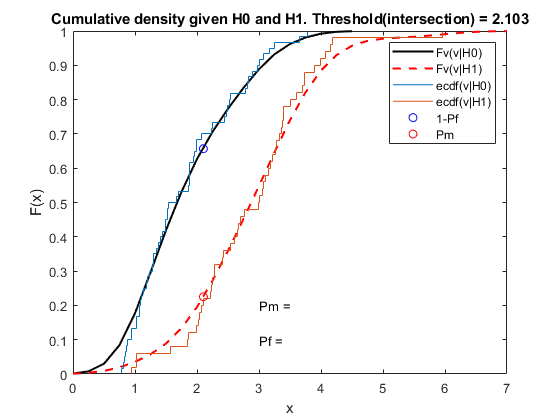


plot(2.103, cdf_abs(one_Pf_CDF_ind)+0.03, 'Ob')
plot(2.103, cdf_pre(Pm_CDF_ind)+0.03, 'Or')
text(3,0.1,'Pf = ')
text(3,0.2,'Pm = ')
legend('Fv(v|H0)', 'Fv(v|H1)', 'ecdf(v|H0)', 'ecdf(v|H1)', ...
    '1-Pf', 'Pm')
title('Cumulative density given H0 and H1. Threshold(intersection) = 2.103')
hold off